# CanlabCore RSA / RSM toolbox -- an object-oriented tour

How the RSA/RSM extension plugs into CanlabCore's object model. Nothing is bolted on: compute_rsm is a METHOD on fmri_data, it returns a new first-class object (rsm), and RSA brain maps come back as statistic_image objects that threshold / montage / region already understand.

Requires: CanlabCore on the path (+ Neuroimaging_Pattern_Masks for load_atlas). Sections 1-9 are self-contained (synthetic fmri_data); Section 10 borrows a sample dataset's brain geometry to run a real rsa_parcelwise / searchlight_rsa.

## 1. Everything starts from a CanlabCore root object: fmri_data

dat = make_synthetic_rsa_data('n_sub', 9, 'n_ses', 5);   % returns a real fmri_data
fprintf('class(dat) = %s\n', class(dat));

class(dat) = fmri_data


disp(head(dat.metadata_table));      % conditions x bodysites x subjects x sessions

       sub        sesno    condition      bodysite   
    __________    _____    _________    _____________

    {'sub-01'}      1       {'hot'}     {'leftface' }
    {'sub-01'}      1       {'hot'}     {'rightface'}
    {'sub-01'}      1       {'hot'}     {'leftarm'  }
    {'sub-01'}      1       {'hot'}     {'rightarm' }
    {'sub-01'}      1       {'hot'}     {'leftleg'  }
    {'sub-01'}      1       {'hot'}     {'rightleg' }
    {'sub-01'}      1       {'hot'}     {'chest'    }
    {'sub-01'}      1       {'hot'}     {'abdomen'  }



## 2. compute_rsm is just a METHOD on fmri_data (the @class extension idiom)

CanlabCore extends a class by dropping a file into @fmri_data/. compute_rsm.m lives there, so MATLAB discovers it as a method -- no classdef edit needed.

fprintf('compute_rsm is a method of fmri_data: %d\n', ismember('compute_rsm', methods(dat)));

compute_rsm is a method of fmri_data: 1


R = compute_rsm(dat, 'group_by', {'condition','bodysite'}, ...
                'subject_var', 'sub', 'metric', 'correlation');

## 3. compute_rsm returns a NEW first-class object: rsm

fprintf('class(R) = %s\n', class(R));      % 'rsm'

class(R) = rsm


R                                          % its disp() reports metric / level / groupings

R =   RSM [24 x 24] x 9 (subject)  metric=correlation
    labels:    hot_abdomen, hot_chest, hot_leftarm, ..., warm_rightface, warm_rightleg
    groupings: hot, imagine, warm, abdomen, chest, leftarm, leftface, leftleg, rightarm, rightface, rightleg
    source:    fmri_data


% ...with its own method surface, exactly like fmri_data / atlas / region:
key = {'plot','mean','to_rdm','to_rsm','fisher_z','subset','reorder','cells', ...
       'ttest_contrasts','reliability','drift','compare','get_by_label'};
fprintf('rsm methods present: %s\n', strjoin(intersect(methods(R), key), ', '));

rsm methods present: cells, compare, drift, fisher_z, get_by_label, mean, plot, reliability, reorder, subset, to_rdm, to_rsm, ttest_contrasts


disp(R.history);                           % provenance list, like every CanlabCore object

    {'2026-07-10 16:32:09: constructed (24x24x9, metric=correlation, level=subject)'}



## 4. Value semantics: transforms return NEW rsm objects (nothing mutates in place)

Rmean = mean(R);            % [k x k x N] -> group-mean rsm
Rdis  = to_rdm(R);          % similarity -> dissimilarity, still an rsm
fprintf('mean(R) -> %s [%s];  to_rdm(R).is_dissimilarity = %d\n', ...
    class(Rmean), num2str(size(Rmean)), Rdis.is_dissimilarity);

mean(R) -> rsm [24  24];  to_rdm(R).is_dissimilarity = 1


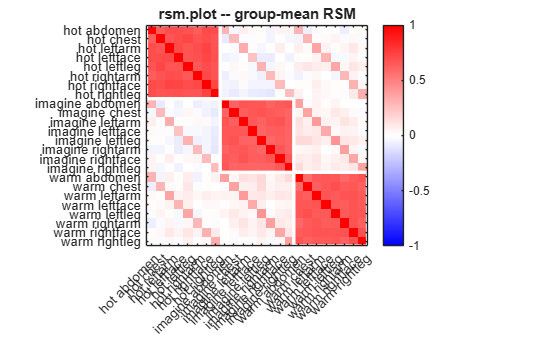

figure('Color','w'); plot(Rmean, 'block_borders_by', 'condition');   % the object draws itself
title('rsm.plot -- group-mean RSM');

## 5. Representational geometry: MDS + dendrogram

The object knows how to project its own geometry. 'mds' lays the k conditions out in 2-D (classical MDS on the dissimilarity) so you can SEE which cluster; 'dendrogram' shows the hierarchical clustering -- both straight off the rsm.

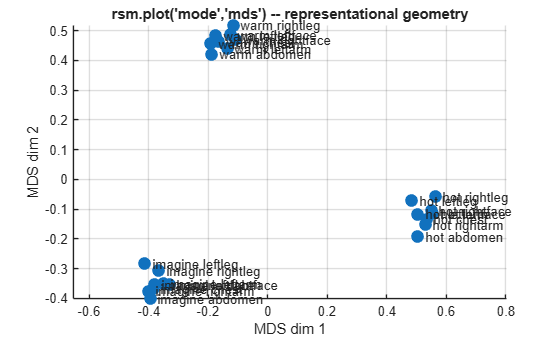

figure('Color','w'); plot(Rmean, 'mode', 'mds');
title('rsm.plot(''mode'',''mds'') -- representational geometry');

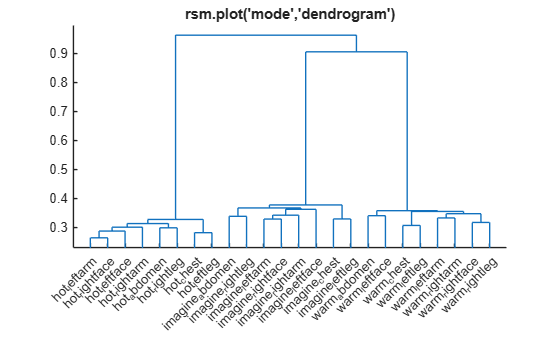

figure('Color','w'); plot(Rmean, 'mode', 'dendrogram');
title('rsm.plot(''mode'',''dendrogram'')');

## 6. Inference lives on the object (declarative contrast specs)

spec = { 'within_hot',  'hot',              [];             % one-sample: within-hot cells
         'HI_vs_HW',    {'hot','imagine'},  {'hot','warm'} }; % paired: HI vs HW blocks
T = R.ttest_contrasts(spec, 'tail','both', 'correction','fdr');
disp(T(:, {'Contrast','Mean_Diff','t','P','FDR_P','sig'}));

      Contrast      Mean_Diff       t           P           FDR_P        sig 
    ____________    _________    _______    __________    __________    _____

    "within_hot"      0.84732     119.12    2.7574e-14    2.7574e-14    true 
    "HI_vs_HW"      -0.039645    -7.8577    4.9681e-05    4.9681e-05    true 



## 7. Model RDMs: build them, DISPLAY them, then compare

Static constructors turn metadata into hypothesis (model) RDMs -- same-vs- different matrices you can look at, then test the brain geometry against.

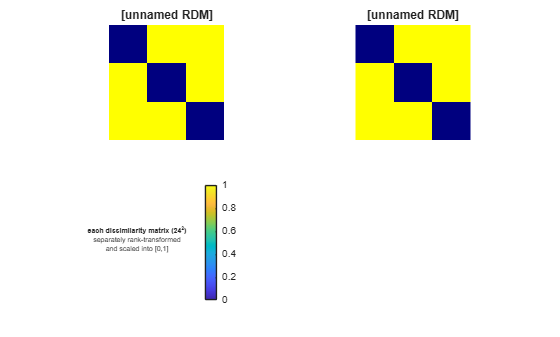

parts = split(string(Rmean.labels), '_');                         % "condition_bodysite"
condModel = rsm.from_categorical(parts(:,1), 'name', 'Condition'); % same-condition RDM

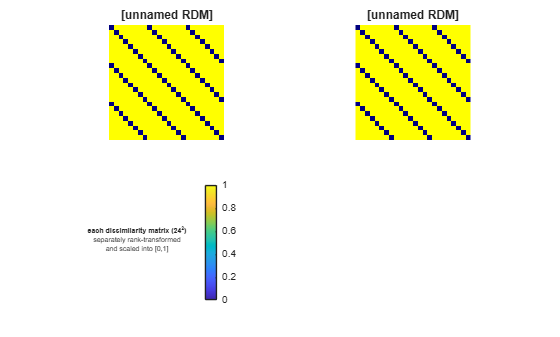

bodyModel = rsm.from_categorical(parts(:,2), 'name', 'Bodysite');  % same-bodysite RDM

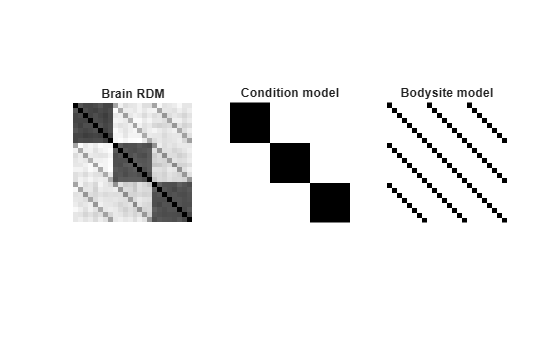

figure('Color','w'); colormap(gray);
subplot(1,3,1); imagesc(to_rdm(Rmean).dat); axis image off; title('Brain RDM');
subplot(1,3,2); imagesc(condModel.dat);     axis image off; title('Condition model');
subplot(1,3,3); imagesc(bodyModel.dat);     axis image off; title('Bodysite model');

% Formal comparison (Nili et al. 2014): brain geometry vs each model RDM.
result = R.compare({'condition','bodysite'}, 'correlation_type','kendall_taua');

rsm.compare: 2 models, 9 subjects, kendall_taua correlation.


fprintf('\nFormal RDM comparison (brain geometry vs model):\n');


Formal RDM comparison (brain geometry vs model):


for i = 1:numel(result.candidate_names)
    fprintf('  vs %-9s model: r=%+.3f  p=%.3g\n', ...
        result.candidate_names{i}, result.r_mean(i), result.relatedness_p_corr(i));
end

  vs condition model: r=+0.425  p=0.00391
  vs bodysite  model: r=+0.053  p=0.00195


## 8. Multilevel modeling: rsa_lme (another fmri_data method)

RSA as a mixed-effects model. Each row is a within-subject condition-pair similarity; predictors are same-condition / same-bodysite / same-session; Subject is a random effect. Returns a standard MATLAB LinearMixedModel, so every fitlme tool (anova, coefCI, random effects, LRT) works on it.

mdl = dat.rsa_lme('predictors', {'condition','bodysite','sesno'}, 'subject_var', 'sub');

assemble_lme_table: 64260 rows, 9 subjects, 3 predictors, 0 interactions
rsa_lme: fitting formula:
  Y ~ SameCondition + SameBodysite + SameSesno + (1 | Sub)
  (n=64260 rows, 9 subjects)
rsa_lme: LME fit complete. AIC=-152636.1, BIC=-152581.6, logLik=76324.0


disp(mdl.Coefficients(:, {'Name','Estimate','SE','tStat','pValue'}));


    Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                     Estimate     SE            tStat     pValue    
    {'(Intercept)'  }        0.0057668     0.0022526      2.56      0.010469
    {'SameCondition'}          0.66091    0.00062021    1065.6             0
    {'SameBodysite' }          0.34757    0.00090428    384.36             0
    {'SameSesno'    }        0.0039951    0.00073766    5.4159    6.1213e-08



% dat.rsa_compare_models(...) does the nested-model LRT/AIC ladder over these.

## 9. Subject-consistency count-maps & count-tables (paper-ready reporting)

Beyond the group effect, you usually report HOW MANY subjects show it. The count_* methods count, per RSM cell / block / contrast / model / region, how many subjects meet a criterion and return both a count-MAP (imagesc-able) and a count-TABLE carrying the group effect + p (via the shared hrf_group_stats permutation engine when it is on the path, else a built-in one-sample t).

cm = R.count_map('Granularity', 'contrasts', 'Contrasts', { ...
        struct('within', 'hot',  'between', 'warm',    'name', 'hot>warm'), ...
        struct('within', 'warm', 'between', 'imagine', 'name', 'warm>imag') });

Unrecognized method, property, or field 'count_map' for class 'rsm'.

disp(cm.table(:, {'name_a', 'count', 'n', 'proportion', 'group_p'}));

% count_models: which candidate model RDM best fits each subject?
mc = R.count_models({'condition', 'bodysite'}, 'Winner', 'exclusive');
disp(mc.table(:, {'model', 'wins', 'n_sig', 'group_mean_r'}));
% figure; R.count_map('Granularity', 'blocks', 'doplot', true);   % block heatmap

## 10. RSA results flow BACK into the CanlabCore ecosystem (statistic_image)

rsa_parcelwise and searchlight_rsa are methods on fmri_data / image_vector that return statistic_image objects -- a CanlabCore root type. So RSA brain maps plug straight into threshold / montage / region / table.

rsa_parcelwise / searchlight_rsa need data in a real brain space, so here we borrow a sample dataset's geometry (its volInfo) and plant the same condition x bodysite structure into it -- giving a spatially-valid fmri_data.

base = load_image_set('emotionreg');                        % real volInfo / MNI space
nvox = size(base.dat, 1); rng(7);
conds = {'hot', 'warm', 'imagine'}; sites = {'arm', 'leg', 'face', 'back'}; nsub = 8;
cp = randn(nvox, numel(conds)); sp = 0.3 * randn(nvox, numel(sites));
Xb = []; sid = {}; cv = {}; bv = {};
for s = 1:nsub
    for ci = 1:numel(conds)
        for bi = 1:numel(sites)
            Xb(:, end+1) = cp(:, ci) + sp(:, bi) + 0.7 * randn(nvox, 1);  %#ok<SAGROW>
            sid{end+1} = sprintf('sub%02d', s);  %#ok<SAGROW>
            cv{end+1}  = conds{ci};              %#ok<SAGROW>
            bv{end+1}  = sites{bi};              %#ok<SAGROW>
        end
    end
end
braindata = base; braindata.dat = Xb; braindata.removed_images = 0;
braindata.image_names = ''; braindata.fullpath = '';
braindata.metadata_table = table(sid(:), cv(:), bv(:), ...
    'VariableNames', {'subject_id', 'condition', 'bodysite'});

atlas = select_atlas_subset(load_atlas('canlab2024'), 1:16);   % subset for speed

% (a) rsa_parcelwise -> statistic_image contrast map
res = rsa_parcelwise(braindata, 'atlas', atlas, ...
    'group_by', {'condition', 'bodysite'}, 'subject_var', 'subject_id', ...
    'metric', 'correlation', 'contrasts', {'hot_vs_warm', 'hot', 'warm'}, ...
    'correction', 'fdr', 'tail', 'right', 'verbose', false);
fprintf('\nrsa_parcelwise -> res.maps.hot_vs_warm is a %s\n', class(res.maps.hot_vs_warm));
mt  = threshold(res.maps.hot_vs_warm, 0.05, 'unc');         % the SAME threshold() as any stat map
reg = region(mt);                                           % -> region objects
fprintf('thresholded RSA map -> %d region objects (region/table/montage all apply)\n', numel(reg));
figure('Color', 'w'); montage(mt);                          % the SAME montage()

% (b) searchlight_rsa -> statistic_image: slide a sphere, correlate each local
%     RSM with the condition model. Restrict to the atlas for a fast demo.
bd_roi = apply_mask(braindata, atlas);
sl = searchlight_rsa(bd_roi, 'condition', 'radius', 3, ...
    'group_by', {'condition', 'bodysite'}, 'subject_var', 'subject_id', ...
    'metric', 'correlation', 'compare', 'spearman', 'verbose', false);
fprintf('searchlight_rsa -> sl.maps.condition is a %s\n', class(sl.maps.condition));
figure('Color', 'w'); montage(sl.maps.condition);          % local-geometry match map

% (c) region consistency count-map: how many subjects show hot>warm, per parcel.
regcnt = count_regions(res.per_parcel_rsms, 'Atlas', atlas, ...
        'Contrasts', { struct('within', 'hot', 'between', 'warm', 'name', 'hotVsWarm') });
disp(regcnt.region_table(:, {'Region', 'count', 'n', 'group_p_corr', 'sig'}));
% figure; montage(regcnt.maps.hotVsWarm);   % statistic_image count-map on the brain

## Summary

The RSA toolbox is not a silo. It speaks fmri_data on the way IN (compute_rsm / rsa_lme / rsa_parcelwise / searchlight_rsa are methods), returns a new first-class rsm object with a CanlabCore-style method surface (plot incl. MDS & dendrogram, cells, ttest_contrasts, compare, count_map/models/regions), and hands RSA brain maps back out as statistic_image objects -- so it composes with region, fmridisplay, montage, threshold and the rest of the toolbox.